# Manufacturing Analytics and Predictive Maintenance | Try It

Beginner activity for MATLAB Online using a synthetic manufacturing dataset. Try the apps first; use the solution Live Script if you need the answer key.

**Important:** The data and labels are synthetic, illustrative, and not PTTGC operating limits or validated failure predictions.

## Learning goals

Inspect data quality, explore process-quality relationships, and try regression/classification apps without writing a full analysis from scratch.

## 1. Load and inspect

Upload the data folder with this Live Script to MATLAB Drive. Set Current Folder to the folder containing this script, then run each section.

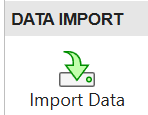

% data = readtable(fullfile("data","synthetic_manufacturing_sensor_data.csv"));
% head(data)
% summary(data)

## 2. Check data quality | Your turn

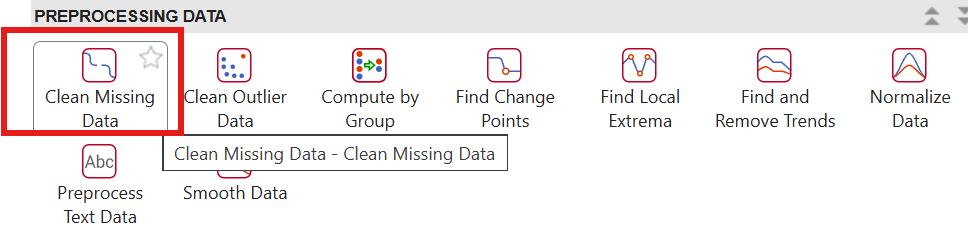

Open Data Cleaner from Apps. 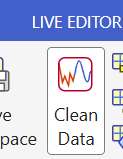

Inspect missing values and compare cleaning options. Do not overwrite the source. Ask why the values are missing before choosing an operational treatment.

## 3. Explore equipment behavior | Your turn

% assetToExplore = "EXTR-01";
% assetRows = data.AssetID == assetToExplore;
% plot(data.Timestamp(assetRows),data.Vibration_mm_s(assetRows),".-")
% xlabel("Time"); ylabel("Vibration (mm/s)"); title("Synthetic vibration trend"); grid on

If available, open Time Series Anomaly Detector. 

Select one asset vibration signal, inspect detected points, and record method/settings. An anomaly is a clue, not proof of failure.

## 4. Explore product quality | Your turn

% scatter(data.Temperature_C,data.MeltFlowIndex_g_10min,24,data.Pressure_bar,"filled")
% xlabel("Temperature (°C)"); ylabel("Melt flow index (g/10 min)"); title("Synthetic process conditions and quality"); colorbar; grid on

Open Regression Learner.

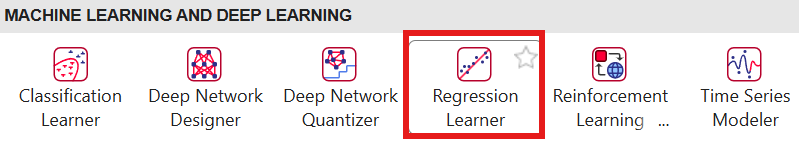

 Set MeltFlowIndex_g_10min as response. Use numeric process/sensor columns as predictors. Exclude Timestamp, AssetID, and ConditionLabel. Train a model and compare observed vs predicted values.

## 5. Explore equipment condition | Your turn

ConditionLabel has Normal, Watch, and Critical categories generated from synthetic rules; these are not observed breakdown events.

Open Classification Learner. 

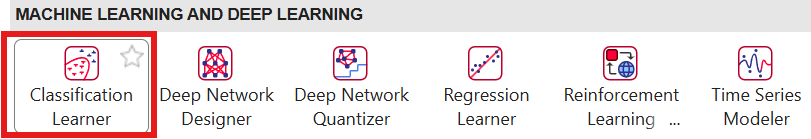

Set ConditionLabel as response, use numeric process/sensor columns as predictors, and exclude Timestamp, AssetID, and MeltFlowIndex_g_10min. Train a model, inspect the confusion matrix, and note the hardest class.

## 6. Reflect

Is the data sampled at the right rate? Are readings synchronized with asset, operating mode, and maintenance history? Could the same asset appear in training and validation data? What action should an alert trigger, and who validates it?